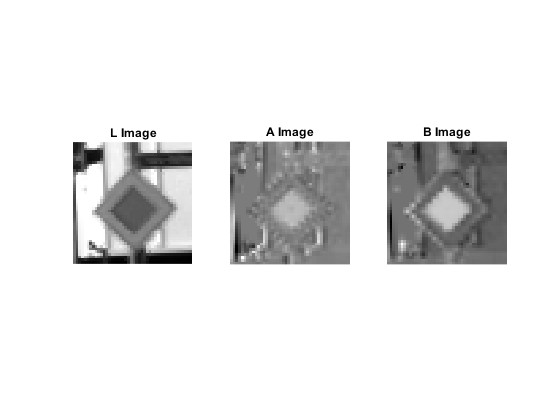

A = exist('ds', 'var');
if ~A
    ds = imageDatastore(["Train1\Train1\", "Train2\Train2\"], "LabelSource","foldernames", "IncludeSubfolders",true);
    ds = ds.shuffle();
end

[data, info] = ds.read();
[FILA, COLUMNA, CANALS] = size(data);

%figure; imshow(data);
%preProcesing:
%data = histeq(data);

imgLAB = rgb2lab(data);
imgAB = imgLAB(:,:,2:3);

figure
subplot(1, 3, 1);
imshow(imgLAB(:, :, 1), []);
title('L Image', 'FontSize', 20);
subplot(1, 3, 2);
imshow(imgLAB(:, :, 2), []);
title('A Image', 'FontSize', 20);
subplot(1, 3, 3);
imshow(imgLAB(:, :, 3), []);
title('B Image', 'FontSize', 20);

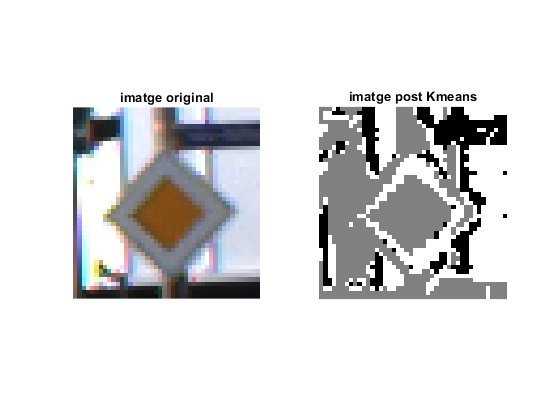


vectAB = reshape(imgAB, FILA*COLUMNA, 2); %[(a,b);.;...]

nColors = 3; %Blanc, Negre i Color senyal
figure
subplot(1,2,1)
imshow(data); title('imatge original');
[cluster_idx, cluster_center] = kmeans(vectAB,nColors,'distance','cityblock');
resultats = reshape(cluster_idx, FILA,COLUMNA);
subplot(1,2,2)
imshow(resultats, []), title('imatge post Kmeans');

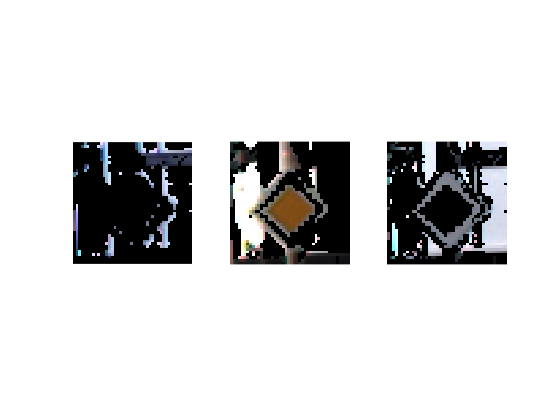


aux = 1;
figure; title("Segmentacions")
for n=1:nColors
    maskN = resultats == n; % 1/true -> blanc
    clusterN = data .* uint8(maskN);
    subplot(1, nColors, aux);
    imshow(clusterN);
    aux = aux + 1;
end

Un cop tenim els clusters, provem d'extreure el color predominant:

colorMarkers = zeros(nColors,2);

for n=1:nColors
    maskN = resultats == n; % 1/true -> blanc
    clusterN = imgAB .* double(maskN);
    colorMarkers(n,1) = mean2(clusterN(:,:,1)); %a
    colorMarkers(n,2) = mean2(clusterN(:,:,2)); %b
end




Color Blanc -> L pròxima a 100 (>90)

Color blanco en imagen logica ==> 1

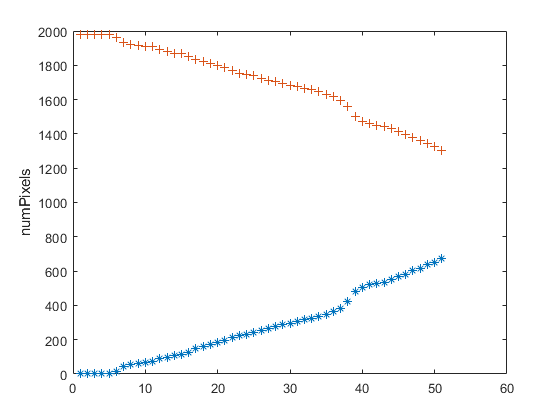

for it=0:50
    e = sum(sum(imgLAB(:,:,1)<=it));
    r(it+1) = e;
end

for it=0:50
    e = sum(sum(imgLAB(:,:,1)>=it));
    r2(it+1) = e;
end
figure
plot(r, '*'); %negres
hold on
plot(r2, '+');%blancs
ylabel numPixels

% WHITE = imgLAB(:,:,1) > 42.10;
% 
% BLACK = imgLAB(:,:,1) <= 10;
% 
% figure
% subplot(1,3,1);
% imshow(WHITE); title white
% subplot(1,3,2)
% imshow(BLACK); title black